% AE6705 MATLAB code
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Time 
t_interr = 15000 / 3e+6;

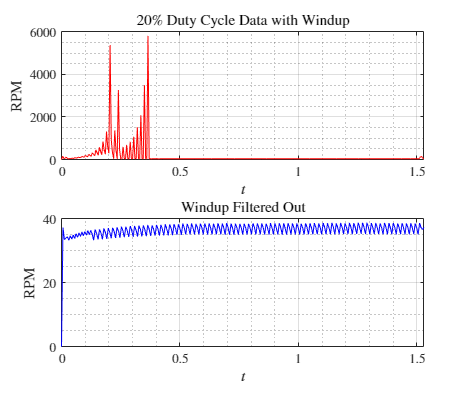

% DC 20%
data = csvread("dc20.csv");
T = t_interr * length(data);
data = [0; data];
fdata1 = data(data < 40);
t = linspace(0,T,length(data));
ft1 = linspace(0,T,length(fdata1));
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    subplot(2,1,1)
    plot(t,data,'-r')
    title('20\% Duty Cycle Data with Windup')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
    subplot(2,1,2)
    plot(ft1,fdata1,'-b')
    title('Windup Filtered Out')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
saveas(fig,'outputs/dc20_plot.png')

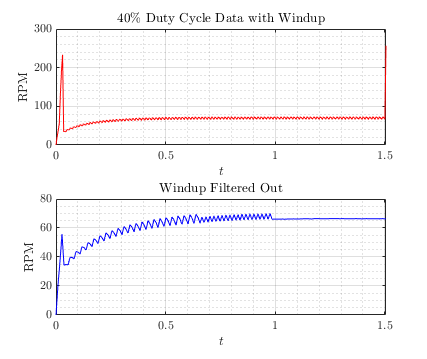

% DC 40%
data = csvread("dc40.csv");
T = t_interr * length(data);
data = [0; data];
fdata2 = data(data < 70);
t = linspace(0,T,length(data));
ft2 = linspace(0,T,length(fdata2));
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    subplot(2,1,1)
    plot(t,data,'-r')
    title('40\% Duty Cycle Data with Windup')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
    subplot(2,1,2)
    plot(ft2,fdata2,'-b')
    title('Windup Filtered Out')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
saveas(fig,'outputs/dc40_plot.png')

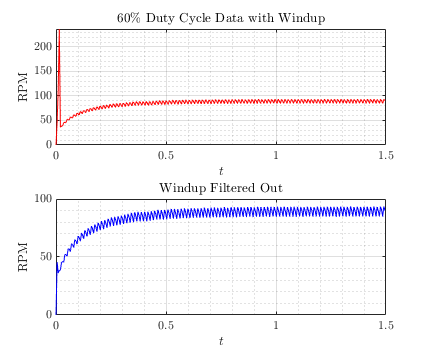

% DC 60%
data = csvread("dc60.csv");
T = t_interr * length(data);
data = [0; data];
fdata3 = data(data < 100);
t = linspace(0,T,length(data));
ft3 = linspace(0,T,length(fdata3));
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    subplot(2,1,1)
    plot(t,data,'-r')
    title('60\% Duty Cycle Data with Windup')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
    subplot(2,1,2)
    plot(ft3,fdata3,'-b')
    title('Windup Filtered Out')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
saveas(fig,'outputs/dc60_plot.png')

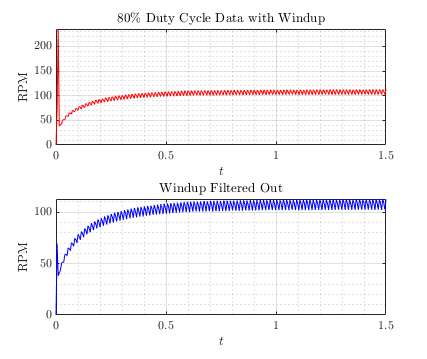

% DC 80%
data = csvread("dc80.csv");
T = t_interr * length(data);
data = [0; data];
fdata4 = data(data < 120);
t = linspace(0,T,length(data));
ft4 = linspace(0,T,length(fdata4));
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    subplot(2,1,1)
    plot(t,data,'-r')
    title('80\% Duty Cycle Data with Windup')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
    subplot(2,1,2)
    plot(ft4,fdata4,'-b')
    title('Windup Filtered Out')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
saveas(fig,'outputs/dc80_plot.png')

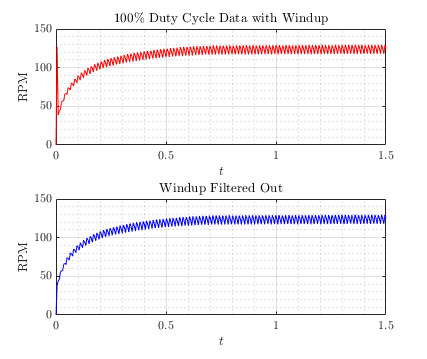

% DC 100%
data = csvread("dc100.csv");
T = t_interr * length(data);
data = [0; data];
fdata5 = data;
fdata5(2) = [];
t = linspace(0,T,length(data));
ft5 = linspace(0,T,length(fdata5));
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    subplot(2,1,1)
    plot(t,data,'-r')
    title('100\% Duty Cycle Data with Windup')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
    subplot(2,1,2)
    plot(ft5,fdata5,'-b')
    title('Windup Filtered Out')
    xlabel('$t$')
    ylabel('RPM')
    grid on; grid minor; box on; 
saveas(fig,'outputs/dc100_plot.png')

% Computing the time constant and the gain
K = mean(fdata5(100:end));
fval = fdata5(end);
idx = max(find(abs(fdata5-fval)>=0.37*fval));
tau = ft5(idx);

% Verify with simulink model
res = sim("motor_model.slx");

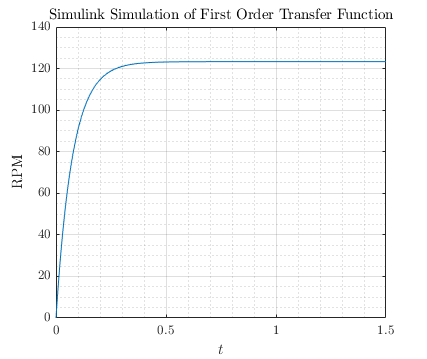

fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(res.tout, res.simout.signals.values);
    grid on; grid minor; box on; 
    title("Simulink Simulation of First Order Transfer Function")
    xlabel('$t$')
    ylabel('RPM')
saveas(fig,"outputs/model_resp.png")

% Computing the time constant and gains for the other duty cycles
Ks = [0 0 0 0 0];
taus = [0 0 0 0 0];
fts = {ft1 ft2 ft3 ft4 ft5};
ct = 1;
for fd = {fdata1 fdata2 fdata3 fdata4 fdata5}
    k = mean(fd{1,1}(100:end));
    fv = fd{1,1}(end);
    i = max(find(abs(cell2mat(fd)-fv)>=0.37*fv));
    ftemp = fts{1,ct};
    toe = ftemp(i);
    Ks(ct) = k ;
    taus(ct) = toe;
    ct = ct + 1;
end